# **电子信息工程建模与仿真作业二**

**姓名：李锦川   班级：119070201   学号：11907980422**

**P2.1 采用双层 BP 神经网络进行数据拟合，建立一个正弦波发生器，其中隐含层的神经元个数 为 6, 隐含层采用对数 S 型激活函数，输入矢量和目标矢量如下所示**


$$p=0:\frac{\pi }{30}:2\pi$$



$$t=\sin \left(p\right)$$


*要求：     1) 建立 feedforwardnet 神经网络 *

*                2) 对建立的网络进行培训学习 *

*                3) 用培训后的网络对输入矢量 p 进行计算，并输出 a *

*                4) 计算输出 a 与目标值 t 的差*

*                5) 用 bar 函数绘制误差曲线 *

*                6) 用 plotfa 函数绘制目标值 t 以及网络的实际输出值*

p=0:pi/30:2*pi;  %p=1x61:    0    0.1047    0.2094    0.3142    0.4189    0.5236    ...
t=sin(p);  %t=1x61:    0    0.1047    0.2094    0.3142    0.4189    0.5236    ...
net=feedforwardnet([61,6]);  %建立feedforwardnet 神经网络 
net=train(net,p,t);
a=net(p)  %!用培训后的网络对输入矢量 p 进行计算

a =     0.0710    0.1045    0.1957    0.3090    0.4068    0.5000    0.5878    0.6691    0.7310    0.8090    0.8980    0.9136    0.8877    0.9406    0.9752    1.0000    0.9945    0.9781    0.9461    0.9135    0.8633    0.8090    0.7431    0.6691    0.5706    0.5003    0.4070    0.3092    0.2081    0.1047    0.0001   -0.1044   -0.1804   -0.3089   -0.4066   -0.4999   -0.5877   -0.6690   -0.7430   -0.8089   -0.8659   -0.8908   -0.9510   -0.9781   -1.0464   -1.0000   -0.8649   -0.8727   -0.9511   -0.9135


e0=t-a  %!计算输出 a 与目标值 t 的差

e0 =    -0.0710    0.0000    0.0122   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0122    0.0000   -0.0320   -0.0000    0.0634    0.0375    0.0193    0.0000    0.0000    0.0000    0.0049    0.0000    0.0028    0.0000    0.0000   -0.0000    0.0172   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0002   -0.0275   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0227   -0.0000   -0.0000    0.0518   -0.0000   -0.1296   -0.1055   -0.0000   -0.0000


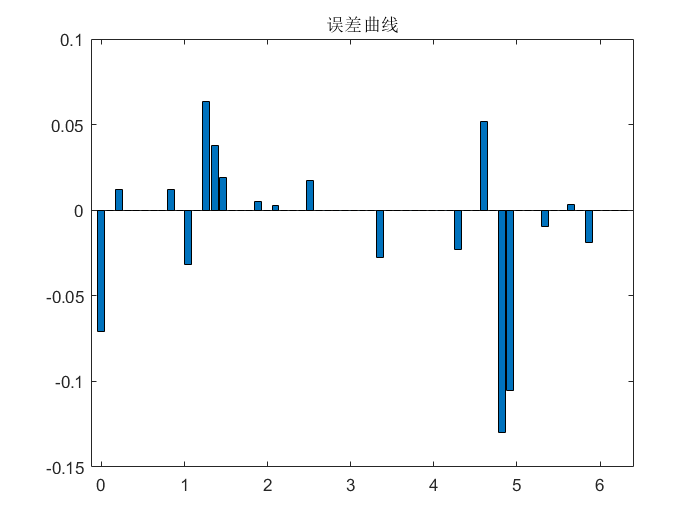

          Use BAR to make bar plots.
 


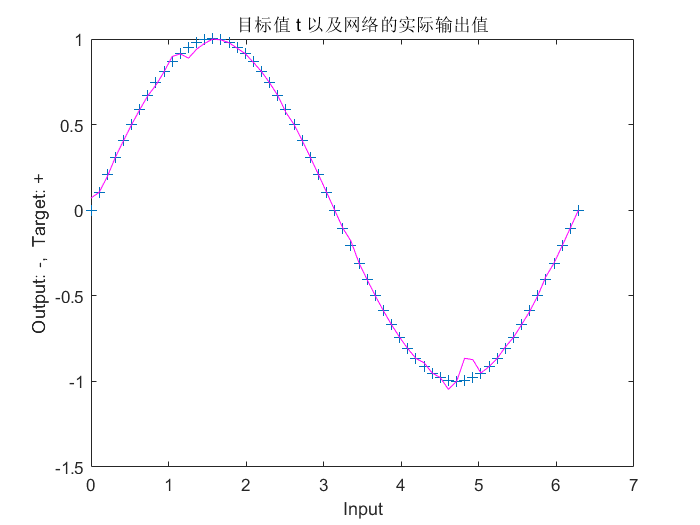

bar(p,e0),title("误差曲线")  %!用 bar 函数绘制误差曲线
plotfa(p,t,p,a),title("目标值 t 以及网络的实际输出值")  %!用 plotfa 函数绘制目标值 t 以及网络的实际输出值

**P2.2 已知数字滤波器的性能指标如下所示**


$$\begin{array}{l}
\omega p=0\ldotp 25\pi ,\;\textrm{Ap}=0\ldotp 25\textrm{dB}\\
\omega s=0\ldotp 3\pi ,\;\textrm{As}=50\textrm{dB}
\end{array}$$


*要求:        1) 用哈明窗窗函数法设计滤波器。*

*                2) 计算所需要的滤波器阶数 *

*                3) 用 freqz 函数绘制滤波器的幅度响应|𝐻𝐻(𝜔𝜔)|及相位响应*

*                4) 用 stem 函数绘制滤波器的单位抽样响应 h(n)*

wp=0.2*pi;
ws=0.3*pi;
width=ws-wp;
M=ceil(6.6*pi/width)+1;
disp(['所需滤波器阶数为',num2str(M)])  %!计算所需要的滤波器阶数

所需滤波器阶数为67


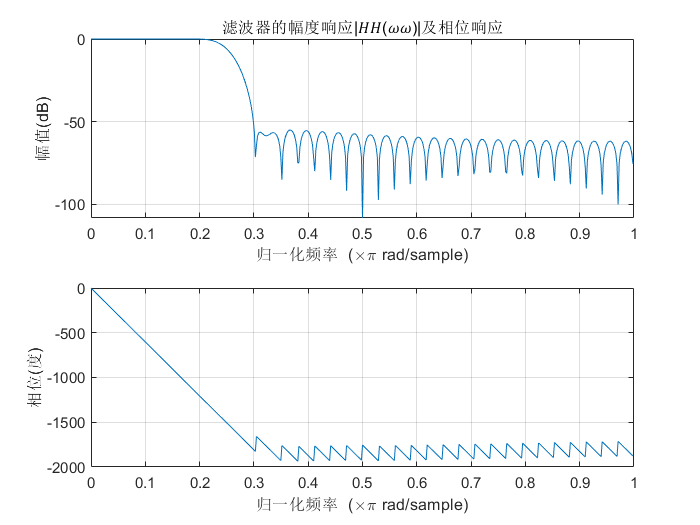

n=0:M-1;
wc=(wp+ws)/2;
hd=ideallp(wc,M);
h=hd.*hamming(length(hd));
freqz(h),title("滤波器的幅度响应|𝐻𝐻(𝜔𝜔)|及相位响应")  %!用 freqz 函数绘制滤波器的幅度响应|𝐻𝐻(𝜔𝜔)|及相位响应

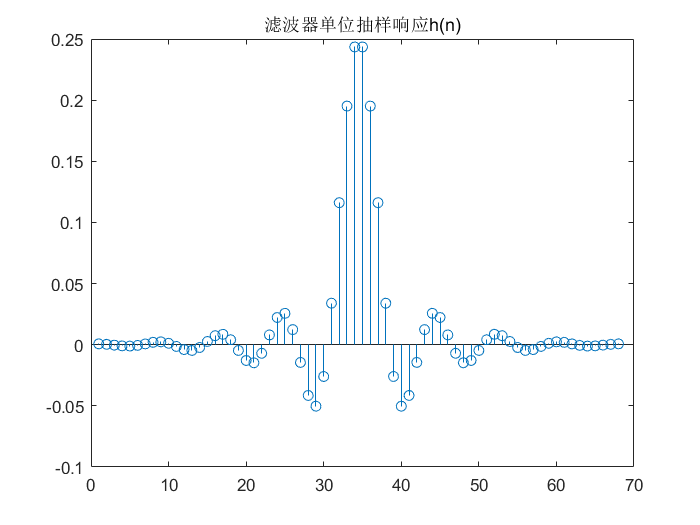

stem(h)  %!用 stem 函数绘制滤波器的单位抽样响应 h(n)
title("滤波器单位抽样响应h(n)")

function h=ideallp(omc,M)
% M=2*alpha
n=(0:M)'-M/2;
h=(omc/pi)*ones(size(n));
i=find(n);
h(i)=sin(omc*n(i))./(pi*n(i));
end